# Manusscript

This document is a manusscript in Swedish for all of the code-related assignments. It aims to intuitvely explain what parts of the coding process that should be highlighted.

# Exempel 1

## Generell polynominterpolation, samma exempel som i videon

Givet datasetet nedan, konstruera ett interpolationspolynom som går genom punkterna i datasetet.


$$\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right)$$


*MATLAB (inbyggda funktioner)*

Låt oss börja med det grunddläggande, att lägga in alla punkter. Jag antar att du är bekant med grunderna i MATLAB om du kollar på denna video, men om inte, så arbetar MATLAB genom att se variabler som matriser.

Jag kommer att skapa en matris som innehåller alla x-värden, och en som innehåller alla y-värden från de punkter vi ska arbeta med.

Ett problem som kan uppstå i MATLAB är att gamla referenser till värden på variabler finns kvar även om ditt program körts klart. För att motverka detta lägger jag till tre rader längst upp i skriptet.

clear all; close all; clc;
x = [2; 4; 6];
y = [3.2; 2; 1.23];

   Eftersom MATLAB arbetar med matriser kan jag förtydliga att de variabler vi precis skapat har följande format: $\vec x=\pmatrix{2&4&6},
\vec y = \pmatrix{3.2&2&1.23}$ 

Nu är det som tur är väldigt enkelt. Vi har tre punkter och därför ska vi ha gradtal 2, enligt minnesregeln: gradtal = antal punkter - 1. Jag har flera gånger tidigare i videon återkommit till att alla polynom kan skrivas genom att variera en uppsättning koefficienter. För andragradspolynom är den generella formeln $y=c_1 x^2 +c_2 x+c_3$ och vi söker koefficienterna $c_{1,} c_2 ,c_3$.

Genom att göra följande anrop:

coefficients = polyfit(x,y,2)

coefficients =     0.0538   -0.9225    4.8300


Får vi fram dessa från MATLAB direkt! Ordningen av utdatan är $c_{1,} c_2 ,c_3$ och syntaxen är polyfit(<x-data>, <y-data>, <önskat gradtal>)

Vi vill nu ta fram polynomets värden i alla x-värden mellan 2 och 6. Om vi tittar på vår vektor x som vi redan skapat, innehåller denna endast x-värdena för precis vår indata och inte för resten av intervallet. För att få en vektor som innehåller alla x-värden mellan 2 och 6, kan vi använda oss av linspace. 

Om jag skriver linspace(2,6), får jag en vektor som uppfyller detta.

Men eftersom detta skript som vi skriver nu kommer vara basen för många av de andra kodexemplen som jag kommer visa, kommer jag göra det lite dynamiskt genom att istället komma åt första och sista värdet i x-vektorn, så koden fortfarande fungerar om du har andra datapunkter.

poly_x = linspace(min(x), max(x)); % Här väljer du intervallet som polynomet ska plottas i.

Nu ska vi ta fram värdena som polynomet med koefficienterna som vi sparat ovan ger ut på intervallet från första till sista punkten. För detta har MATLAB en funktion som helter "polyval" som tar in först koefficienterna och sedan det intervall som vi vill få fram y-värdena på.

poly_y = polyval(coefficients, poly_x);

Den sista pusselbiten är att plotta allt, vilket kan göras med koden nedan. Vi börjar med vårt dataset x och y, dvs. punkterna vi fått från uppgiften. "o" säger till MATLAB att plotta punkterna som prickar i grafen och inte förbundna med någon linje eller liknande. Vi plottar även polynomet på en gång.

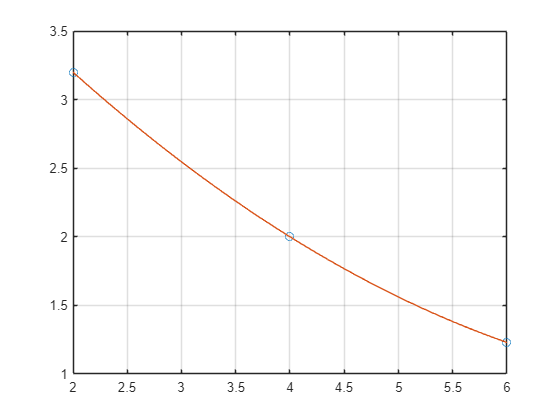

plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

*MATLAB (utan inbyggda funktioner)*

Nu ska vi koda samma exempel som tidigare fast vi ska koda interpolationskoden själv, dvs. vi ska skriva koden för polyfit och polyval själva.

Detta eftersom du ibland kan bli efterfrågad att inte använda några inbyggda specialfunktioner i MATLAB förutom de mest grundläggande, exempelvis linspace och plot.

Här är det bra att vara bekant med det första räkneexemplet i videon, eftersom jag inte kommer förklara allt lika grundligt som där.

Vi har tre punkter vilket enligt formeln gradtal = antal punkter - 1 säger att vi ska anpassa ett andragradspolynom. Kom ihåg att detta gäller då du ska utföra "klassisk" polynominterpolation, dvs. inte kubiska splines, minstakvadratmetoden, eller liknande.

I videoexemplet visade jag att principen var att ta de givna x-värdena för varje punkt och de givna y-värdena och mata in det i den allmäna ekvationen för ett andragradspolynom i det här fallet.

Jag kommer även i detta exempel koda dynamiskt så att du enkelt kan ändra din indata och den allmäna ekvationen för ett polynom.

Därför kommer jag vara generell. Låt oss tillta på en enda punkt först, och låt oss vara generella och kalla den för $\left(x_1 ,y_1 \right)$. Om vi infogar $x_1 ,y_1$ i den allmäna ekvationen för ett andragradspolynom $y=c_1 x^2 +c_2 x+c_3$ får vi:

$y_1 =c_1 {x_1 }^2 +c_2 x_1 +c_3$ vilket kan skrivas på matrisform som: $\underbrace{\pmatrix{x_1^2&x_1&1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1}}_{\vec b}$

Om du inte hängde med, testa att göra detta själv för hand eller repetera hur man skriver om ekvationssystemet på matrisform.

Om vi adderar en till punkt $\left(x_2 ,y_2 \right)$ och infogar den på samma sätt som vi precis gjorde med första punkten, blir ekvationssystemet enligt nedan:


$$\underbrace{\pmatrix{x_1^2&x_1&1\cr x_2^2&x_2& 1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1\cr y_2}}_{\vec b}$$


Vi har tre punkter i vårt exempel, så den slutliga "allmäna" matrisen skulle bli enligt nedan:


$$\underbrace{\pmatrix{x_1^2&x_1&1\cr x_2^2&x_2& 1\cr x_3^2&x_3& 1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1\cr y_2\cr y_3}}_{\vec b}$$


Jag har även döpt matriserna A, x och b. A och b kommer vi behöva tänka på i vår kod.

Låt oss skapa en kod som interpolerar ett andragradspolynom över godtyckliga tre datapunkter i MATLAB, och göra den dynamisk så det är lätt att ändra gradtal om så krävs!

Den här koden gick jag igenom i förra exemplet. Här rensar vi bara MATLAB från variabler som hänger kvar från tidigare skript, och vad vi också gör är att vi infogar all vår indata.

clear all; close all; clc;
x = [2; 4; 6];
y = [3.2; 2; 1.23];

Nu ska vi fokusera på hur vi kan skapa matrisen A. Låt oss först börja med vad vi behöver göra:

vi behöver gå igenom alla datapunkter och skapa en egen rad i matrisen för respektive datapunkt.

Låt oss först initiera A-matrisen, och sedan ta fram hur många datapunkter vi har. Vi vet ju att vi har tre stycken, men vi kan göra koden mer dynamisk genom att använda length-funktionen, som kommer ge ut hur många element som finns i x-matrisen som vi precis skapade. Det finns tre x-värden inlagda vilket svarar mot hur många datapunkter vi har.

A = [];
NUMBER_OF_DATAPOINTS = length(x);

Nu ska vi gå igenom alla datapunkter vilket kan göras med följande for-statement. Detta är en räknare där a i vårt fall (eftersom vi har tre värden) kommer ha värdena 1, 2, 3.

För att minnas hur varje rad i matrisen ska se ut, låt mig fokusera på en rad i den fullständiga interpolationsmatrisen som vi nyss tog fram ovan.

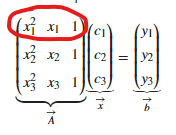

Låt oss också notera att det enda som skiljer raderna åt i A-matrisen är x-värdena.

Så generellt kan en rad i matrisen uttryckas som:


$$\matrix{x_i^2&x_i&1}$$


I for-loopen kan vi komma åt x-värdet för den aktuella datapunkten genom att accessa index i i listan med datapunkter.

Vi kan därför skriva ett dynamiskt uttryck för att skapa raden som svarar mot punkten med x-värdet index i som: [x(i)^2 x(i) 1]

För att lägga till denna rad i slutet av A-matrisen, kan vi skriva A(i,:) =. Det kan se lite förvirrande ut från början, men låt mig förklara vad det betyder.

i betyder att vi kommer sätta rad med index i för matrisen A till det som står till höger om likhetstecknet, dvs. den dynamiska formeln för en rad i matrisen som vi precis tagit fram.

Men eftersom vi har skrivit en komplett rad som består av flera kolumner och inte bara ett enda element, måste vi lägga till kolonen för att indikera att vi matar in flera kolumner. Du kan testa utan, men du kommer få ett felmeddelande.

% Exemplet använder ett andragradspolynom
for i=1:NUMBER_OF_DATAPOINTS
    A(a,:) = [x(i)^2 x(i) 1];
end

Genom att skriva ut värdet på matrisen A kan vi se att vi fått samma resultat som exemplet i videon.

disp(A)

     4     2     1
    16     4     1
    36     6     1



Om vi tar fram videon kan vi validera att det är samma svar, förutom att alla kvadrerade värden har räknats ut.

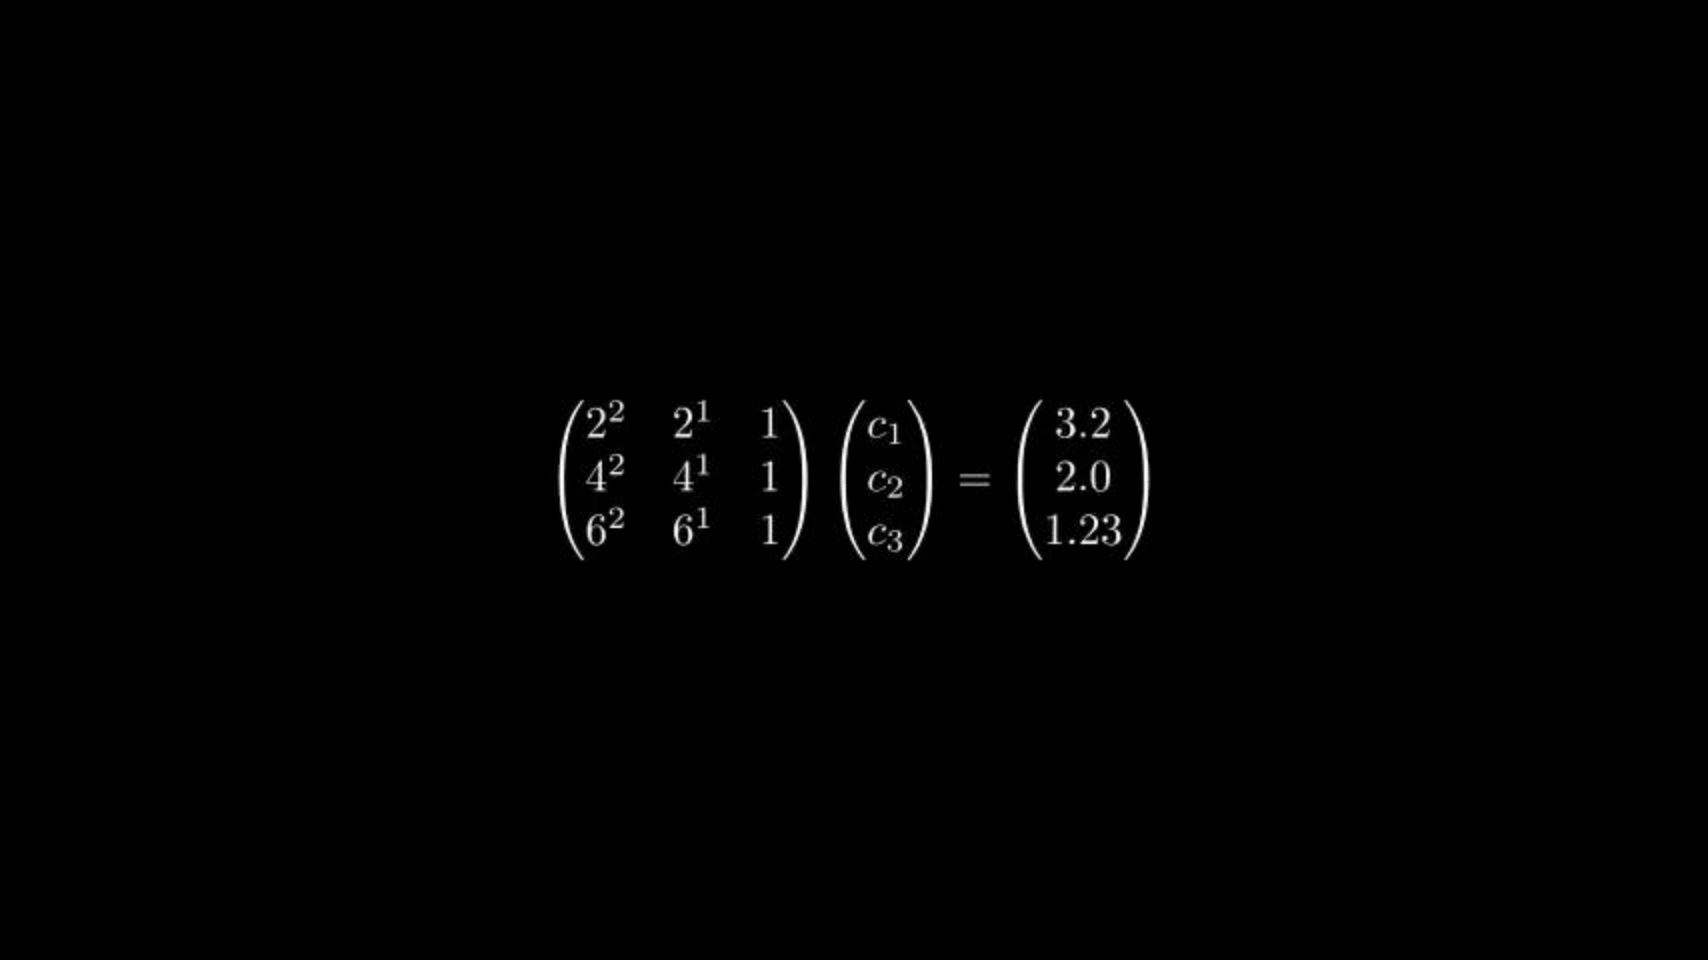

Minns tillbaka till det allmäna exemplet för polynominterpolation som jag gick igenom i videon. Vi ska lösa ett ekvationssystem $A\vec{\;x} =\vec{\;b}$. Vi har tagit fram A, och ska nu ta fram b.

Som vi även kan notera både från bilden jag precis visade och den allmäna formeln vi tog fram ovan så består högerledet i ekvationen vi ska lösa för att ta fram koefficienterna av y-värdena för de punkter vi interpolerar över. Men, vi har redan matat in alla dessa värden i vår kod! När vi skapade y-variabeln i början, matade vi ju in alla y-värden.

Så att ta fram b-matrisen i vårt ekvationssystem och skapa den dynamiskt i MATLAB är busenkelt! Det är bara ta värdena vi redan matat in. Jag skapar en ny matris b som jag sätter till samma värden som vi matat in i y, bara för att vara övertydlig. För att lösa ett ekvationssystem på formen $A\vec{\;x} =\vec{\;b}$ skriver du A \ b i MATLAB:

b=y;
coefficients = A \ b

coefficients =     0.0538
   -0.9225
    4.8300


Vi kan som du ser ovan validera att koefficenterna stämmer.

Nu när vi vet koefficienterna ska vi ta fram x-värdena och y-värdena som vårt interpolationspolynom ger ut. Om du har sett exemplet med MATLABs inbyggda funktioner som precis visades i videon, kommer det jag gör nu vara hyfsat bekant.

Jag kan kort påminna om vad som behöver göras. Vi har matat in x-värden ovan, men de har grova steg mellan varandra - det skiljer 2 steg i x-led mellan varje datapunkt i vårt fall.

För att få interpolationspolynomets värden i alla x-värden mellan startpunkten och slutpunkten, använder vi oss av linspace, som kommer ge ut en vektor med x-värden separerade med ett mycket finare steg.

poly_x = linspace(min(x), max(x));

Det som skiljer åt nu från vårt tidigare exempel med MATLABs inbyggda funktioner för interpolation är att vi inte kan använda oss av polyval, utan istället får skriva in polynomets ekvation manuellt.

Kom ihåg att poly_x kommer vara en variabel med massa x-värden mellan 2 och 6. coefficents är en variabel med tre element som är c1, c2, c3.

Vår generiska polynomekvation för ett andragradspolynom är $y=c_1 x^2 +c_2 x+c_3$ . MATLAB har ett fiffigt sätt att räkna ut y-värdena för alla x-värden i vår poly_x vektor på en rad, vilket beror på att MATLAB ser alla variabler som matriser.

c1 kan vi få från coefficients(1), c2 från coefficients(2). För att skapa en vektor som innehåller alla y-värden för respektive x-värde i vår variabel poly_x, kan vi mata in poly_x överallt där x förekommer i den generiska polynomekvationen. Däremot måste vi göra en liten ändring alla gånger x förekommer upphöjt till ett tal. Vi vill ju ha polynomets y-värden för respektive x-värde, och vill därför höja upp varje individuellt element i variabeln poly_x. För att indikera detta så använder vi oss av .^. Annars är det som sagt i princip bara skriva av den generiska ekvationen!

poly_y=coefficients(1)*(poly_x.^2)+coefficients(2)*(poly_x)+coefficients(3);

Detta är som sagt en konsekvens av att MATLAB hanterar variabler som matriser och hur MATLAB hanterar matrismultiplikation och multiplikation med koefficienter.

För att plotta punkterna använder vi oss precis som i exemplet med inbyggda funktioner av plot(). Det enda egentligen värt att notera här är att "o" gör så att punkterna som finns i x och y plottas som cirklar på skärmen, vi kommer se de sen när vi plottar.

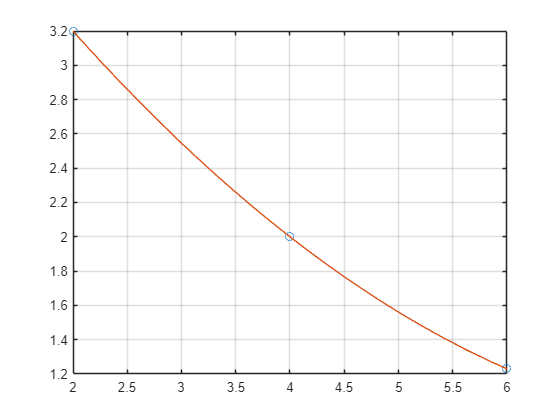

plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

Och här är återigen våra punkter markerat i blått och vårt interpolationspolynom markerat i rött!

*Fotnot*

Låt mig lite kort visa vad som skulle ändras om du hade fler eller färre punkter givet till dig,

dvs. om du exempelvis blev efterfrågad att anpassa ett tredjegradspolynom.

Det enda du skulle behöva ändra, förutom att mata in andra punkter i x- och y-variablerna, är följande:

Du behöver i for-loopen ändra raden där du skapar A-matrisen. Om du har ett polynom av lägre gradtal, alltså ett förstagradspolynom, skulle raden längst till vänster försvinna.

Du kan enklast validera detta på papper eller genom att räkna igenom övriga räkneexempel i denna video.

 Raden skulle alltså bli

Tvärtom, om du hade ett tredjegradspolynom, skulle det tillkomma en till kolumn:

# Exempel 2

## Minsta kvadratmetoden, samma exempel som i videon

Givet datasetet nedan, konstruera ett minstakvadratanpassat andragradspolynom till datapunkterna.


$$\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right),\left(-6,1\ldotp 23\right),\left(-4,2\right),\left(-2,3\ldotp 2\right),\left(0,4\right),\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right),\left(8,0\ldotp 8\right),\left(10,0\ldotp 55\right)$$


Vad som är så praktiskt med MATLAB är att MATLAB detekterar automatiskt när ett ekvationssystem är överbestämt, dvs. när det behöver lösas med minstakvadratmetoden, och gör det åt oss.

Dvs. vi behöver inte ens multiplicera med A-transponat som jag visat att vi gör i viden utan MATLAB sköter det åt oss!

Vi kan med andra ord använda exakt samma koder som vi gjorde i Exempel 1 eftersom uppgiften ber oss anpassa ett andragradspolynom. Har du alltså inte kollat på Exempel 1, gör det innan du fortsätter.

Så, nu ska vi göra en ytterst liten modifikation till koden från uppgift 1. Det enda vi behöver göra är att ändra våra variabler som innehåller datapunkter!

Låt oss först göra detta för vår kod som innehåller MATLABs inbyggda interpolationsfunktioner, dvs. polyval och polyfit.

*MATLAB (inbygda funktioner)*

clear all; close all; clc;
% START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
x = [-10; -8; -6; -4; -2; 0; 2; 4; 6; 8; 10];
y = [0.55; 0.8; 1.23; 2; 3.2; 4; 3.2; 2; 1.23;0.8; 0.55];
% SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
coefficients = polyfit(x,y,2)

coefficients =    -0.0285    0.0000    2.9199


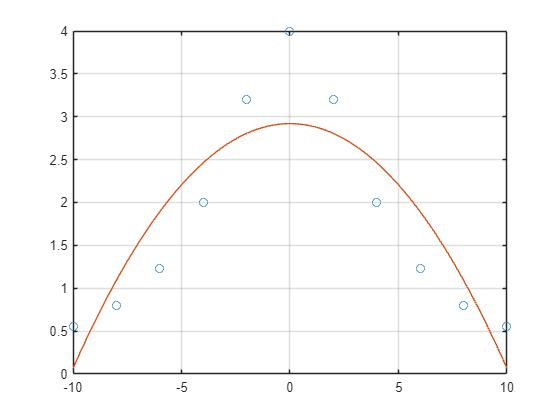

poly_x = linspace(min(x), max(x)); % Här väljer du intervallet som polynomet ska plottas i
poly_y = polyval(coefficients, poly_x);
plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

Om vi kör koden och plottar polynomet ser vi mycket riktigt att vi har en fin minstakvadratanpassad andragradskurva.

Låt oss sedan göra detta för vår kod där vi själva skrev interpolationsfunktionerna. Även här behöver vi bara ändra datapunkterna.

*MATLAB (utan inbyggda funktioner)*

clear all; close all; clc;
% START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
x = [-10; -8; -6; -4; -2; 0; 2; 4; 6; 8; 10];
y = [0.55; 0.8; 1.23; 2; 3.2; 4; 3.2; 2; 1.23;0.8; 0.55];
% SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
NUMBER_OF_DATAPOINTS = length(x);
A = [];
% Exemplet använder ett andragradspolynom
for i=1:NUMBER_OF_DATAPOINTS
    A(a,:) = [x(i)^2 x(i) 1];
end
disp(A)

   100   -10     1
    64    -8     1
    36    -6     1
    16    -4     1
     4    -2     1
     0     0     1
     4     2     1
    16     4     1
    36     6     1
    64     8     1
   100    10     1



b=y;
coefficients = A \ b

coefficients =    -0.0285
    0.0000
    2.9199


poly_x = linspace(min(x), max(x));
poly_y=coefficients(1)*(poly_x.^2)+coefficients(2)*(poly_x)+coefficients(3);
plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

Vi validerar att vi även här får en fin minstakvadratanpassad andragradskurva.

# Exempel 3

## Centrering, samma exempel som i videon

Givet datasetet nedan, konstruera ett interpolationspolynom som går genom punkterna i datasetet.


$$\left(1568,20\right),\left(1570,24\right),\left(1572,22\right)$$


Eftersom centering, precis som jag sa i videon, är väldigt lik generell polynominterpolation, kan vi bara göra några små ändringar till våra skript från ovan.

En annan sak jag tidigare nämnde är att i princip alla kodexempel kommer bygga på koden från Exempel 1, så om du inte kollat igenom Exempel 1 bör du göra det,

för jag kommer endast förklara de ändringar från koden som användes i det exemplet!

Det enklaste här är att använda exemplet där vi implementerade interpolationen själv, eftersom det krävs minst ändringar.

Låt mig påminna vad som händer vid centrering. Om jag tappar dig har jag gått igenom det mer noga i videon. Vid centering av ett polynom, i vårt fall ett andragradspolynom, ändras den generella polynomekvationen lite:

I tidigare exempel är vi vana vid $y=c_1 x^2 +c_2 x+c_3$. Vid centrering har vi istället$y=c_1 \left({\left.x-m\right)}^2 +c_2 \left(x-m\right)+c_3 \right.$, där m är en punkt vi väljer för att centrera kring.

Detta är bra för att ekvationssystemet som ska lösas inte innehåller lika stora tal jämfört med om vi bara hade matat in indatan i vår kod från Exempel 1.

Låt oss först upppdatera vår indata. Vi väljer precis som i videon att centera kring punkten 1570, vilket ligger på index 2 i listan av vår indata. Jag kallar x-värdet vi centrerar kring för m.

clear all; close all; clc;
% START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
x = [1568;1570;1572];
y = [20;24;22];
m = x(2); % Punkt som centreras kring
% SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL

Eftersom den generiska ekvationen ändrats jämfört med när vi bara utförde klassisk polynominterpolation i Exempel 1 så behöver vi även uppdatera de ställena i koden där vi har referenser till den generiska polynomekvationen.

Låt oss återigen repetera skillanden mellan formeln för ett generiskt andragradspolynom och formeln för ett generiskt andragradspolynom med centrering kring en punkt med x-värde m:

$y=c_1 x^2 +c_2 x+c_3$. VS $y=c_1 \left({\left.x-m\right)}^2 +c_2 \left(x-m\right)+c_3 \right.$

Tittar vi noga kan vi notera att den enda skillnaden är att x har bytts ut mot x-m.

Vi kan göra samma sak i vår kod bara, dvs. varje gång vi inkluderar ett x-värde kan vi byta ut det mot x-m.

Låt oss börja med att ändra raden där vi skapar A-matrisen.

*Observera *att (i) ska vara kvar efter x, eftersom x(i) motsvarar x-värdet för den aktuella iterationen.

NUMBER_OF_DATAPOINTS = length(x);
A = [];
% Exemplet använder ett andragradspolynom
for i=1:NUMBER_OF_DATAPOINTS
    % START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
    A(i,:) = [(x(i)-m)^2 (x(i)-m) 1];
    % SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
end
disp(A)

     0     0     1
     4     2     1
    16     4     1



I övrigt är de följande raderna likadana som koden från Exempel 1.

b=y;

coefficients =    -0.7500
    3.5000
   20.0000


coefficients = A \ b
poly_x = linspace(min(x), max(x));

Den andra och sista ändringen vi ska göra i koden vi sett tidigare är som jag precis nämde att byta ut alla referenser till x i den generiska polynomekvationen till x-m. Den andra och sista referensen är där vi har löst våra koefficenter och ska räkna ut y-värdena. Här använder vi poly_x-vektorn istället för x-vektorn, så det vi gör är att jämföra alla element i poly_x med vårt centrerade värde m. poly_x byts alltså ut till poly_x-m

poly_y=coefficients(1)*((poly_x-m).^2)+coefficients(2)*(poly_x-m)+coefficients(3);

Även om poly_x är en variabel som innehåller massa lagrade tal och m bara är ett enda tal, kommer MATLAB automatiskt att subtrahera allt innehåll i poly_x med värdet m.

Sedan är koden som vanligt. Vi kan plotta för att se att vi fått samma resultat.

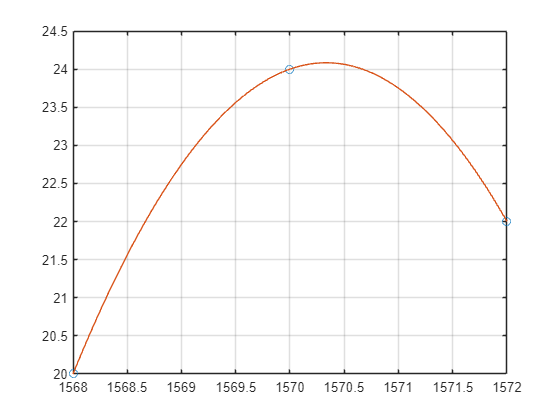

plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

Vi kan återgå till stället där vi outputar hur A-matrisen ser ut.

När vi skrivit ut matrisen ser vi att den innehåller mindre siffror, vilket är snällare för datorn.

Med "snällare för datorn" menar jag att matrisens så kallade *konditionstal *är lägre. Mer om konditionstal kanske du har lärt dig i din kurs om numeriska metoder. I skrivande stund har jag ingen video som går igenom detta men jag länkar till en bra i beskrivningen.

Vi kan kolla på konditionstalet av matrisen A med funktionen cond(). Ju lägre, desto bättre:

cond(A)

Det ser ju bra ut.

*MATLAB (inbygda funktioner)*

MATLABs inbyggda funktion för centering är lite annorlunda eftersom den också **skalar om x- och y-axeln. Om du inte hänger med rekommenderar jag att du försöker förstå dig på exemplet utan inbyggda funktioner istället.**

Det vi måstse ändra är raden då vi använder polyfit. Den måste ändras till detta.

för att MATLAB ska detektera att vi vill använda centering. ~ används för att polyfit returnerar ett värde som innehåller information som vi inte behöver använda. ~ säger till MATLAB att vi ska ignorera det värdet.

Vi lägger här till "mu" på slutet. "mu" är en vektor med två värden, $\mu =\left(\mu_1 ,\mu_2 \right)$ . Se nedan så berättar jag vad den gör.

Vi ändrar sedan när vi tar ut värdena av polynomet till att använda oss av mu-variabeln som vi fått från polyfit ovan:

[] kan du bortse ifrån, det är bara för att mu är det fjärde argumentet till funktionen polyval, så behöver mata in något tomt till det tredje argumentet så MATLAB vet att vi inte vill ändra något speciellt med hänsyn till det.

De två ändringarna jag precis visade är alla ändringar du behöver göra för att använda centrering med polyfit och polyval. Om du undrar vad tusan mu-vektorn gör för något ska jag förklara det nu.

 MATLAB kommer nämligen göra följande: ändra dina infograde x-värden genom att ändra de enligt formeln $\vec x=\frac{\vec x-\mu_1}{\mu_2}$ där $\left(\mu_1 ,\mu_2 \right)$ är två magiska tal som MATLAB räknat ut.

Om du vill veta mer om de hänvisar jag till MATLABs dokumentation.

Det är kanske inte det viktigaste att förstå exakt vad mu-vektorn gör, men det värt att veta att när MATLAB löser för koefficienter så centrerar den inte bara som jag visat ovan, utan dessutom skalar om koordinatysstemet.

Fördelen är att beräkningarna blir ännu snällare för datorn än att bara centrera, men nackdelen är att det kanske inte är lika enkelt att förstå sig på som bara ren centrering.

Den fullständiga ändrade koden blir alltså

clear all; close all; clc;
% START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
x = [1568;1570;1572];
y = [20;24;22];
[coefficients, ~, mu] = polyfit(x,y,2)

coefficients =    -3.0000    1.0000   24.0000


mu =         1570
           2


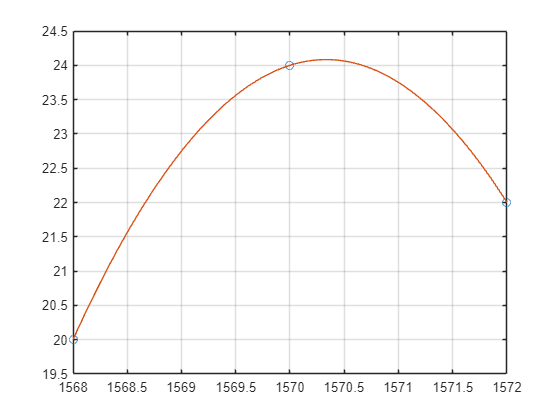

% SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
poly_x = linspace(min(x), max(x)); % Här väljer du intervallet som polynomet ska plottas i
% START RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
poly_y = polyval(coefficients, poly_x, [], mu);
% SLUT RADER SOM ÄNDRATS FRÅN GRUNDLÄGGANDE EXEMPEL
plot(x, y, "o", poly_x, poly_y) % Plotta punkter och polynomet
grid on;

Återigen validerar vi att vår plot ser bra ut.

# Exempel 4

## Splines, samma exempel som i videon

Givet datasetet nedan, konstruera **linjära och kubiska** splines anpassade till datapunkterna.


$$\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right),\left(-6,1\ldotp 23\right),\left(-4,2\right),\left(-2,3\ldotp 2\right),\left(0,4\right),\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right),\left(8,0\ldotp 8\right),\left(10,0\ldotp 55\right)$$


*MATLAB, inbyggda funktioner*

Vi kommer återigen att bygga denna kod på Exempel 1, varianten med inbyggda funktioner, och jag kommer endast förklara vad som skiljer sig mot det exemplet. Därför, kolla igenom exempel 1 innan du kollar igenom detta exempel.

Vi lägger in vår data som vi gjort tidigare, och behåller koden då vi plottar från det grundläggande exemplet. Men som du kanske anar, så är det där vi anpassar själva polynomet som ska ändras

clear all, close all, clc;
x = [-10; -8; -6; -4; -2; 0; 2; 4; 6; 8; 10];
y = [0.55; 0.8; 1.23; 2; 3.2; 4; 3.2; 2; 1.23;0.8; 0.55];
poly_x = linspace(min(x), max(x)); % RAD KVARSTÅR FRÅN GRUNDLÄGGANDE EXEMPEL

Vi kommer istället för som i exempel 1 där jag använde mig av polyfit att använda oss av en MATLAB-funktion som heter griddedInterpolant.

**Observera **att mina datapunkter är åtskiljda med jämna steg, dvs. med 2 steg längs med x-axeln mellan alla punkter i x-vektorn.

Om dina datapunkter INTE är åtskiljda med jämna steg byt griddedInterpolant mot scatteredInterpolant! I övrigt kan du använda samma kod.

Funktionen griddedInterpolant, eller scatteredInterpolant beroende på hur din indata ser ut, ger oss en funktion $f\left(x\right)$ som ger ut ett y-värde som bestäms med hjälp av styckvis interpolation.

I vårt exempel ska vi använda styckvis linjär interpolation, så vi matar in "linear" för att tala om detta till griddedInterpolant:

f = griddedInterpolant(x,y, "linear");

För att få fram alla y-värden kan vi anropa funktionen f(x). Återigen är MATLAB smidiga här eftersom MATLAB som jag tidigare nämnt i ett annat exempel ser på variabler som innehåller flera tal som matriser. Om vi matar in en variabel med flera tal till funktionen f som vi fått tillbaka från griddedInterpolant, kommer vi få tillbaka en vektor med motsvarande y-värden för respektive x-värde.

Med andra ord kan jag få fram alla relevanta y-värden genom att använda vår variabel poly_x som representerar en radda med punkter inom det intervall vi interpolerar över:

poly_y = f(poly_x);

 Jag kan sedan plotta precis som vi gjort innan.

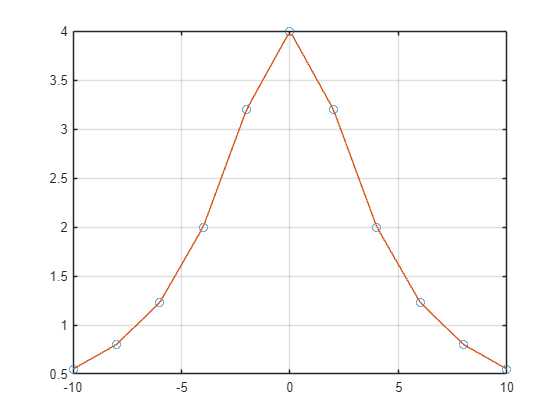

plot(x, y, "o", poly_x, f(poly_y), "-");
grid on;

Som jag även nämner i videon är kubiska splines, dvs. tredjegradspolynom mellan två punkter i taget, definitivt att föredra av många sätt och det vanligaste som du kommer göra. Om vi vill plotta kubiska splines kan vi ändra "linear" i griddedInterpolant till "spline" och plotta enligt nedan

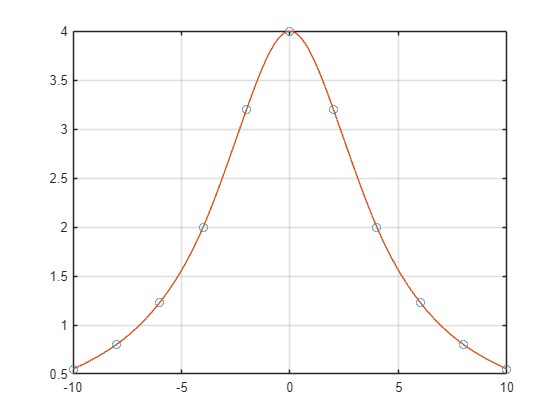

% START RADER SOM ÄNDRATS FRÅN LINJÄRA SPLINES
f = griddedInterpolant(x,y, "spline");
% SLUT RADER SOM ÄNDRATS FRÅN LINJÄRA SPLINES
poly_x = linspace(min(x), max(x));
plot(x, y, "o", poly_x, f(poly_x), "-");
grid on;

Precis som jag även nämnde i videon ser tredjegradssplines mycket jämnare ut än linjär interpolation.

*MATLAB (utan inbyggda funktioner)*

Låt oss nu titta på hur vi kan skapa linjära splines utan att använda oss av griddedInterpolant eller scatteredInterpolant. Återigen kommer vi använda liknande interpolationskod som vi gjorde under Exempel 1 utan inbyggda funktioner. Se därför till att du både förstår metod och kod från det exemplet.

Låt oss nu betrakta det specifika med splines.

Som jag nämnde i videon består splines av separata polynom som konstruerats mellan två punkter i taget.

Men linjär interpolation över två punkter i taget kräver ingen speciell annan metod jämfört med hur vi gör när vi skapar ett "klassiskt" interpolationspolynom, eftersom den grundläggande metoden jag presenterat för linjär interpolation kräver två punkter, inte mer och inte mindre!

Låt oss lägga in vår data:

clear all, close all, clc;
x = [-10; -8; -6; -4; -2; 0; 2; 4; 6; 8; 10];
y = [0.55; 0.8; 1.23; 2; 3.2; 4; 3.2; 2; 1.23;0.8; 0.55];

Låt oss titta på vad vi behöver göra, ett intervall i taget.

Låt oss börja med de två första punkterna $\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right)$.

Allmäna formeln för ett förstagradspolynom är: $y=c_1 x+c_2$ där c1 och c2 ofta kallas för k och m.

Ekvationssystemet som ska lösas för att interpolera mellan dessa två punkter är:


$$\left\lbrace \begin{array}{ll}
0\ldotp 55=-10c_1 +c_2  & \\
0\ldotp 8=-8c_1 +c_2  & 
\end{array}\right.$$


Vi kan skriva om det på matrisform som


$$\underbrace{\pmatrix{-10&1\cr-8&1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2}}_{\vec x}=\underbrace{\pmatrix{0.55\cr 0.8}}_{\vec b}$$


Vårt mål är nu att skapa matriserna, lösa ekvationssystemet och plotta resultatet *för alla* intervall med två datapunkter i taget, dvs. 

x=-10 och x=-8, sedan x=-8 och x=-6, sedan x=-6 och x=-4, osv.

Låt oss först skriva koden för de första två punkterna som i princip är samma som vårt första exempel på interpolation i MATLAB.

Vi skapar matrisen A  och tar fram våra koefficienter enligt nedan:

A = [];
% Exemplet använder ett förstagradspolynom
for a=1:2
    A(a,:) = [x(i) 1];
end

1:2 tar det första två punkterna från x-vektor och skapar exakt samma matris som jag precis tog fram åt oss ovan vilket vi kan validera genom:

disp(A)

   -10     1
    -8     1



Nu kan vi slutligen lösa ekvationssystemet som jag tidigare visat enligt 

b = y(1:2);
coefficients = A \ b;

Där 1:2 som jag precis nämnt tar de första två punkterna från vår indata

Låt oss plotta polynomet och alla datapunkter. Vi ändrar till x(1:2) för att komma åt de två första indatapunkterna.

poly_y = coefficients(1)*x(1:2)+coefficients(2);
plot(x, y, "o", x(1:2), poly_y);

Nu behöver vi hitta ett sätt att göra detta för alla våra datapunkter.

Vi vill skapa en loop som följer följande mönster:

Gå igenom hela datasetet och ge ut intervall med två datapunkter i taget, dvs. 

x=-10 och x=-8, sedan x=-8 och x=-6, sedan x=-6 och x=-4, osv.

Vi kan göra detta genom att gå igenom hela x-vektorn och y-vektorn, vilket jag tidigare har visat i Exempel 1.

i är en räknare som kommer räkna upp från 1 till antal datapunkter (dvs. 11) minus 1. Varför vi behöver subtrahera med 1 kommer du se strax, om du inte kommer ihåg min minnesregel från videon som säger att antal individuella splines-polynom som ska konstrueras följer formeln: antal datapunkter - 1.

Vi kommer ju behöva hämta x- och y-värdena för respektive intervall, dvs. första intervallet är (-10, 0.55), (-8, 0.8). Om vi börjar i första punkten vill vi ha värdena för första punkten och punkten efter.

Vi skriver koden enligt nedan:

NUMBER_OF_DATAPOINTS = length(x);
for i=1:NUMBER_OF_DATAPOINTS-1
    interval_x = x(i:i+1);
    interval_y = y(i:i+1);
end

Vi vill slippa scenariot att vi hamnar i sista punkten och sedan försöker komma åt punkten efter den, för den finns ju inte och då kommer vi få MATLAB att spotta ut ett felmeddelande. När vi skriver i:i+1 får vi punkten som ligger på index i, och på ett index högre, index i + 1. För att slippa hamna på ett index som ligger utanför det sista indexet i x-vektorn subtraherar vi med 1 när vi skapar loopen ovan. Låt oss nu klistra in koden vi tidigare använde för att skapa ett linjärt interpolationspolynom mellan två punkter ovan: 

for i=1:length(x)-1
    interval_x = x(i:i+1);
    interval_y = y(i:i+1);
    % Inklistrad kod från ovan
    A = [];
    % Exemplet använder ett förstagradspolynom
    for i=1:2
        A(i,:) = [x(i) 1];
    end
    b = y(1:2);
    coefficients = A \ b;
    poly_y = coefficients(1)*x(1:2)+coefficients(2);
    plot(x, y, "o", x(1:2), poly_y);
end

Det återstår att få vår tidigare kod att vara dynamisk och skapa samt plotta ett polynom för varje intervall av två punkter.

Till vår hjälp har vi vår nya variabel interval_y och interval_x som kommer vara dynamiska och olika för varje intervall vi går igenom.

Låt oss först fixa så vår kod använder dessa punkter:

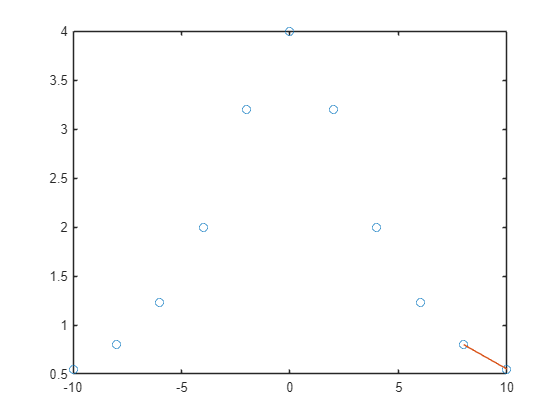

for i=1:length(x)-1
    interval_x = x(i:i+1);
    interval_y = y(i:i+1);
    % Inklistrad kod från ovan
    A = [];
    % Exemplet använder ett förstagradspolynom
    for a=1:2
        A(a,:) = [interval_x(i) 1]; % <-ÄNDRAD RAD FRÅN TIDIGARE KODBLOCK---
    end
    b = interval_y; % <-ÄNDRAD RAD FRÅN TIDIGARE KODBLOCK---Eftersom interval_y redan har längden 2 behöver vi inte indexa de två första elementen som tidigare
    coefficients = A \ b;
    poly_y = coefficients(1)*interval_x+coefficients(2); % <-ÄNDRAD RAD FRÅN TIDIGARE KODBLOCK---
    plot(x, y, "o", interval_x, poly_y); % <-ÄNDRAD RAD FRÅN TIDIGARE KODBLOCK---
end

Som MATLAB fungerar kommer plot()-funktionen endast att visa den senaste plotten från att den anropats, så länge man inte lägger in "hold on". Eftersom vår loop anropar plot()-funktionen 10 gånger, kommer vi behöva lägga in "hold on" efter den så alla plots visas.

Slutligen kan vi göra lite "housekeeping", dvs. lite uppstädning i koden genom att inte plotta datapunkterna i början (x,y) varje gång utan bara en gång.

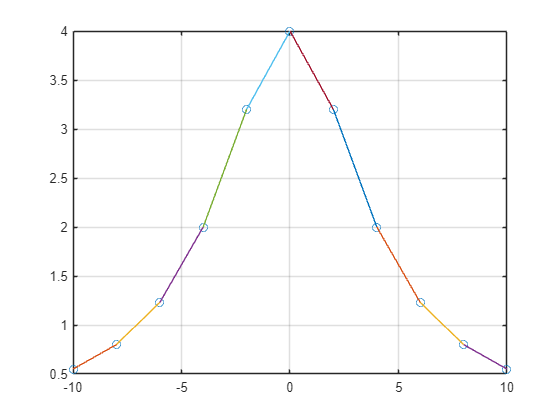

plot(x, y, "o");
hold on;
grid on;
for a=1:length(x)-1
    interval_x = x(a:a+1);
    interval_y = y(a:a+1);
    % Inklistrad kod från ovan
    A = [];
    % Exemplet använder ett förstagradspolynom
    for a=1:2
        A(a,:) = [interval_x(i) 1]; % <-ÄNDRAD RAD FRÅN TIDIGARE KODBLOCK---
    end
    b = interval_y;
    coefficients = A \ b;
    poly_y = coefficients(1)*interval_x+coefficients(2);
    plot(interval_x, poly_y);
    hold on;
end

Styckvisa splines är mer komplicerat